# **Feature Extraction**

## **Data Import**

ds = tabularTextDatastore("Files\*.txt");

## Pre-Processing & Feature Extraction

preDS = transform (ds, @preprocess);
letterDS = transform(preDS, @extractfeatures);

#### Adding Character to data

% example row of processed data * number of files (each in this form)
letterSingleData = read(letterDS)

letterSingleData = 1×25 table
    AspectRatio     MADX       MADY       AvgU       MADU       AvgV      MADV      CorrXY      CorrXP     CorrXU     CorrXV      CorrYP      CorrYU     CorrYV      CorrPU      CorrPV      CorrUV     NumXMin    NumXMax    NumYMin    NumYMax    NumUMin    NumUMax    NumVMin    NumVMax
    ___________    _______    _______    _______    ______    ________    _____    ________    ________    


% all single row data combined to single table
letterdata = readall(letterDS);

% extracting character from files names
letterdata.Character = categorical(extractBetween(ds.Files,"_","_"))

letterdata = 3874×26 table
    AspectRatio      MADX       MADY        AvgU       MADU        AvgV       MADV      CorrXY      CorrXP       CorrXU      CorrXV       CorrYP       CorrYU      CorrYV       CorrPU       CorrPV       CorrUV      NumXMin    NumXMax    NumYMin    NumYMax    NumUMin    NumUMax    NumVMin    NumVMax    Character
    ___________    ________    _______    ________    _______    ________    ______    _____

### Divide data into sets for Training and Testing

% Random number state, for reproducibility
rng(123)  

% Holdout partition to get indices for training and testing
partition = cvpartition(height(letterdata), "HoldOut", 0.25)

partition = Hold-out cross validation partition
   NumObservations: 3874
       NumTestSets: 1
         TrainSize: 2906
          TestSize: 968


indTest = test(partition);
indTrain = training(partition);

% Indexing into data
testdata = letterdata(indTest, :);
traindata = letterdata(indTrain, :);

#### Record of the raw data files corresponding to the training and testing data

% sub-string extraction
files = extractAfter(ds.Files, "Files\");

testfiles = files(indTest);
trainfiles = files(indTrain);

## Distribution

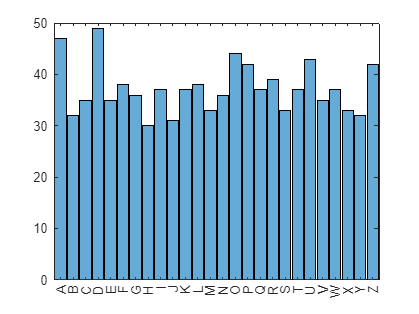

histogram(testdata.Character)

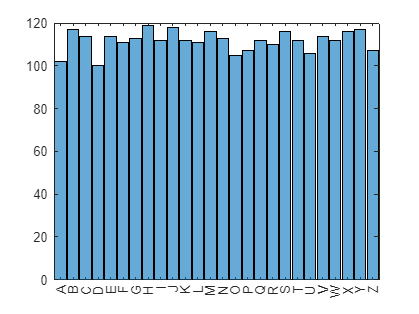

histogram(traindata.Character)

## Data Writing

%save letterfeatures testdata traindata testfiles trainfiles
% wrtiting the complete data to single excel file
writetable(letterdata, "Data\letterComplete.xlsx");

% writing train and test data to their respective files
writetable(traindata, "Data\traindata.xlsx");
writetable(testdata, "Data\testdata.xlsx");

% writing test and train file names
writecell(testfiles, "Data\testFiles.xlsx");
writecell(trainfiles, "Data\trainFiles.xlsx");

## ***Functions***

### function applied on each file and formated to table format*

*single row table, later combined to single table

### Preprocessing

function data = preprocess(data)

    % Normalize time
    data.Time = (data.Time - data.Time(1)) / (data.Time(end) - data.Time(1));
    
    % Fixing aspect ratio to that of screen of writing device
    data.X = 1.5 * data.X;
    
    % Center X & Y at (0,0)
    data.X = data.X - mean(data.X, "omitnan");
    data.Y = data.Y - mean(data.Y, "omitnan");
    
    % Scale to have bounding box area of 1
    scale = 1 / sqrt(range(data.X) * range(data.Y));
    data.X = scale * data.X;
    data.Y = scale * data.Y;
    
    % Calculate derivatives
    data.dXdT = [NaN;diff(data.X)./diff(data.Time)];
    data.dYdT = [NaN;diff(data.Y)./diff(data.Time)];

    % Infinite value -> same values in data.Time
    data.dXdT(isinf(data.dXdT)) = NaN;    
    data.dYdT(isinf(data.dYdT)) = NaN;      
    
    % Smooth derivatives (moving average)
    n = round(0.1 * numel(data.Time));
    data.dXdT = movmean(data.dXdT,n);
    data.dYdT = movmean(data.dYdT,n);

end

### Feature Extraction

function feat = extractfeatures(letter)

    % Correlations
    c = corrcoef (letter{:,2:end}, "Rows", "pairwise");

    % Parameters for finding local mins & maxes
    mp = 0.1;
    derivscale = 2;

    % Calculate features
    feat = [range(letter.Y) / range(letter.X),...                           % aspect ratio
        mad(letter.X), mad(letter.Y),...                                    % deviation for X & Y
        mean(letter.dXdT, "omitnan"), mad(letter.dXdT),...                  % mean and deviation for X' & Y'
        mean(letter.dYdT, "omitnan"), mad(letter.dYdT),...                    
        c(1, 2:end), c(2, 3:end), c(3, 4:end), c(4, end),...                % correlations
        nnz(islocalmin(letter.X, "MinProminence", mp)),...                  % number of local min/max for X & Y
        nnz(islocalmax(letter.X, "MinProminence", mp)),...                    
        nnz(islocalmin(letter.Y, "MinProminence", mp)),...
        nnz(islocalmax(letter.Y, "MinProminence", mp)),...
        nnz(islocalmin(letter.dXdT, "MinProminence", derivscale*mp)),...    % number of local min/max for X' & Y'
        nnz(islocalmax(letter.dXdT, "MinProminence", derivscale*mp)),...       
        nnz(islocalmin(letter.dYdT, "MinProminence", derivscale*mp)),...
        nnz(islocalmax(letter.dYdT, "MinProminence", derivscale*mp))];

    % Combine Features to single row table
    feat = array2table(feat,"VariableNames",...
        ["AspectRatio",...
        "MADX","MADY","AvgU","MADU","AvgV","MADV",...
        "CorrXY","CorrXP","CorrXU","CorrXV","CorrYP","CorrYU","CorrYV","CorrPU","CorrPV","CorrUV",...
        "NumXMin","NumXMax", ...
        "NumYMin","NumYMax",...
        "NumUMin","NumUMax", ...
        "NumVMin","NumVMax"]);

end